# Gaussian processes

A Gaussian process is a set of random variables, any subset of which is multivariate Gaussian, with mean defined by the same mean function and covariance matrix defined by the same covariance function. Let's first plot some Gaussian processes, and then use Gaussian processes for regression.

### The simplest Gaussian process: uncorrelated random variables

The simplest mean function is the zero function, $m(x)=0$, and the simplest covariance function is the identity covariance function, $k(x_i, x_j) = \delta_{ij}$, where $\delta_{ij}$ is the Kronecker delta function. We'll use these for our first example of a Gaussian process. Suppose we have a set of $n$ points $x_1,\ldots,x_n$. The identity covariance function does not depend on the points, so the covariance matrix is simply the $n \times n$ identity matrix. Now, $\mathbf{y} = [y_1, \ldots, y_n]^T$ sampled from $N(0, I)$ is an instantiation of a Gaussian process.

To be concrete, let's choose a 1-dimensional set of regularly-spaced $n$ points $1/n, 2/n, \ldots, 1$, and generate a sample $\mathbf{y}$.

n = 100;
x = (1:n)'/n;
y = randn(n,1);

The values of $y_i$ are not correlated with each other, and the plot of $(x_i,y_i)$ for the $n$ points is what you would expect.

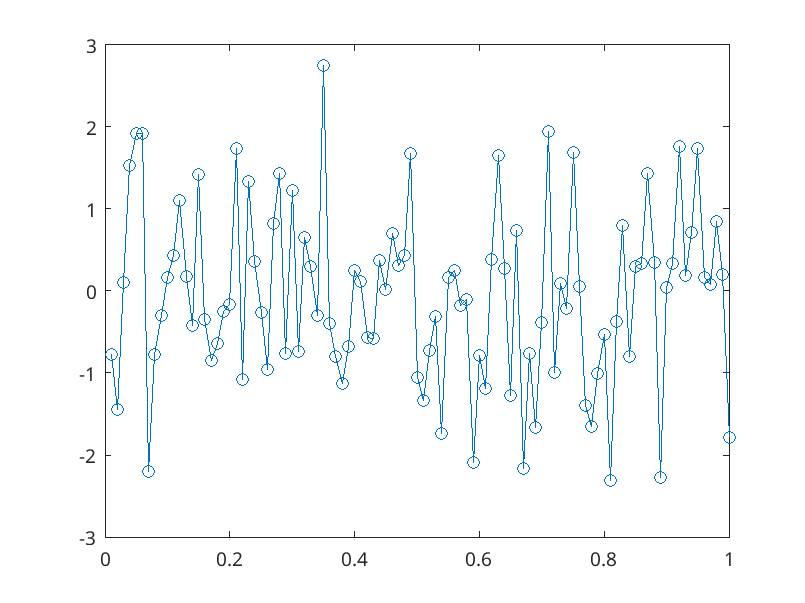

plot(x, y, '-o');

Gaussian processes with entirely uncorrelated random variables are not at all interesting. But they are useful to serve as this first example.

### Correlated random variables

Covariance functions generally assign large covariance to pairs of points that are nearby and small covariance to pairs of points that are far apart. In ML, this means that we assume that a pair of feature vectors $x_i$ and $x_j$ will have more strongly correlated target values $y_i$ and $y_j$, respectively, if the feature vectors are closer together, as measured by the covariance function. An example of such a covariance function is


$$k(x,x') = \exp\big(-\frac{1}{2s^2} (x-x')^2\big)$$


which has the shape of a Gaussian function. The parameter $s$ controls the length scale of the correlations between the points. A larger value of $s$ means that points are correlated over longer distances between points.

Let us plot some instances of Gaussian processes using this covariance function, for different values of $s$. We will also use the zero mean function. Our set of points $x_i$ is the same as above. Define the covariance matrix for this set of points.

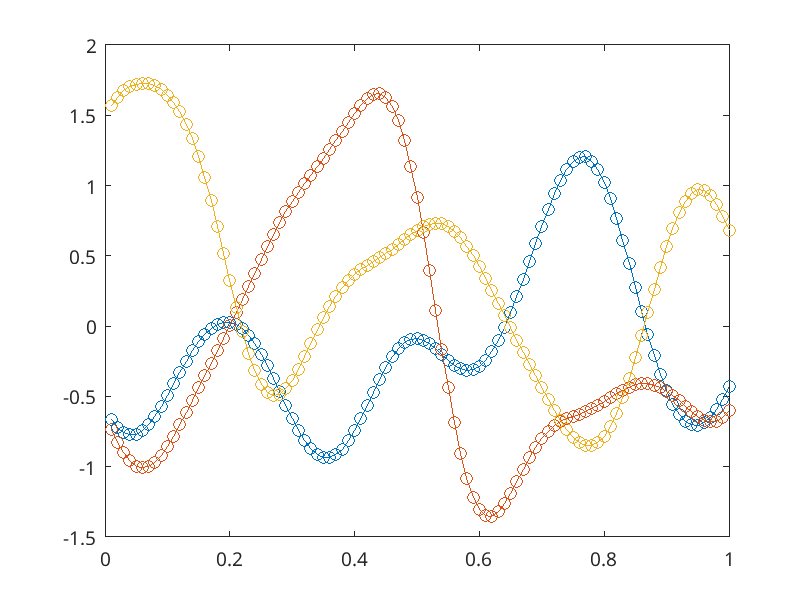

s = 0.1;
K = zeros(n,n);
for i = 1:n
for j = 1:n
  K(i,j) = exp(-0.5/(s^2) * (x(i)-x(j))^2);
end
end
y = mvnrnd(zeros(n,3)', K)';
plot(x, y, '-o');

For a value such as $s=0.1$, the $y_i$ are highly correlated, and the resulting distribution of the $y_i$ looks very smooth. Experiment with different values of $s$ to see how this affects the smoothness. Does the smoothness change if we have a lot more points $x_i$ defined in the same interval [0,1]?

Let's try a different covariance function,


$$k(x,x') = \exp\big(-s |x-x'|\big)$$


called the exponential covariance function. Note that the meaning of $s$ is different here.

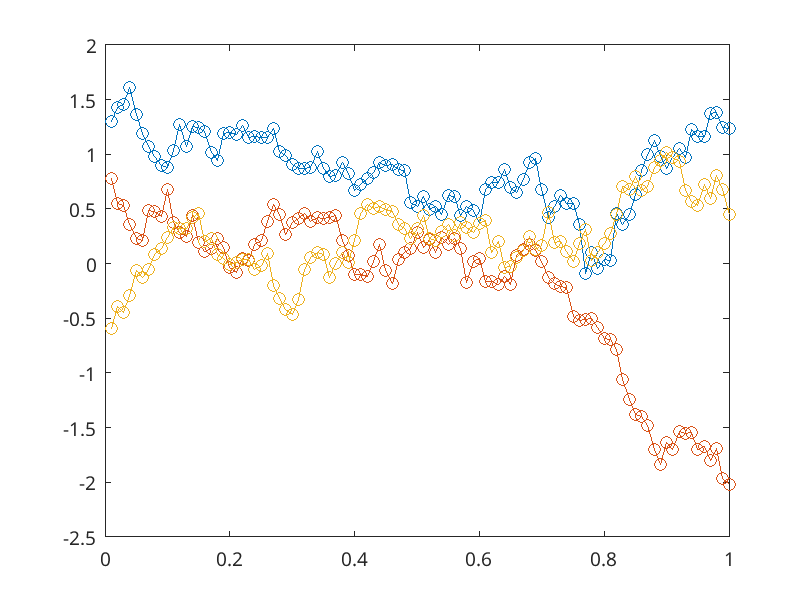

s = 1;
K = zeros(n,n);
for i = 1:n
for j = 1:n
  K(i,j) = exp(-s*abs(x(i)-x(j)));
end
end
y = mvnrnd(zeros(n,3)', K)';
plot(x, y, '-o');

### Gaussian process regression

We drew the above plots with lines between the points to suggest that an instance of a Gaussian process defines a function. This is exactly our aim, and we can imagine that we can define a function implicitly if we have an infinite set of $x_i$ consisting of all possible points at which we want to define a function.

Before we observe any data that we use for regression, the mean function (which is usually chosen to be the zero function) and the kernel function (along with any parameters such as $s$) define a set functions. The Gaussian distribution defines the *prior* probability of each of those functions. You can imagine that a rough function would not be very likely for a Gaussian kernel function with a large length scale.

Once we have observed some data, then the probability of each of the functions changes. This is the *posterior* probability distribution of the functions. Gaussian process regression chooses the most probable function from this posterior distribution of functions.

We'll illustrate Gaussian process regression for synthetic data, where the true function is $\sin(2\pi x)$.

fun = @(x) sin(2*pi*x);

Generate synthetic data.

sigma2 = 0.01;
x = rand(4,1);
y = fun(x) + sqrt(sigma2)*randn(size(x));

Form covariance matrix.

n = length(x);
K = zeros(n,n);
s = 0.1;
for i = 1:n
for j = 1:n
  K(i,j) = exp(-0.5/(s^2) * (x(i)-x(j))^2);
end
end
C = K + sigma2*eye(n);

Calculate predictions.

xx = 0:0.01:1;
yy = [];
vari = [];
for xval = xx
  kvec = exp(-0.5/(s^2) * (x-xval).^2);
  yval = kvec'*(C\y);
  yy = [yy yval];
  vari = [vari (sigma2+1-kvec'*(C\kvec))];
end

Finally, plot the results.

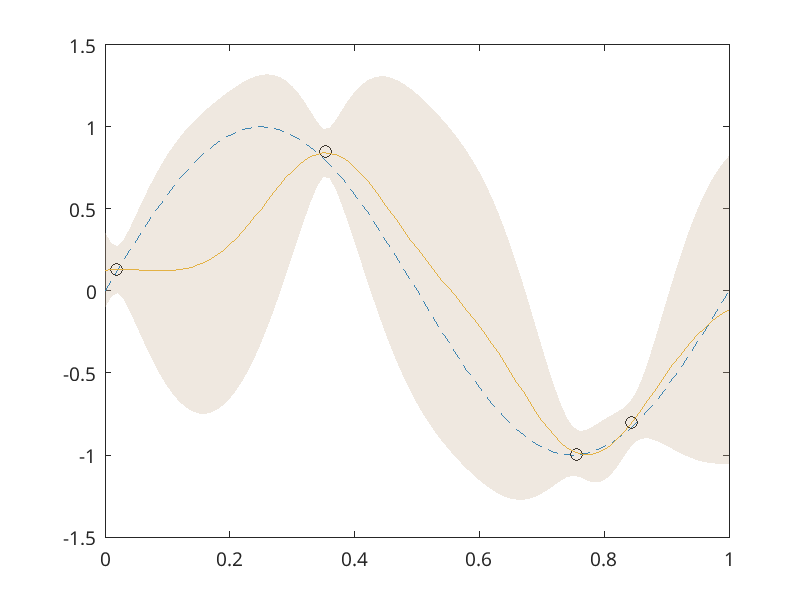

clf
plot(xx,fun(xx),'--');   % true function
hold on
plot(x,y,'ko');          % data points
plot(xx,yy);             % mean function
lo = yy-sqrt(vari);
hi = yy+sqrt(vari);
h = patch([xx xx(end:-1:1) xx(1)], [lo hi(end:-1:1) lo(1)], 'b');
set(h, 'EdgeAlpha',0, 'FaceColor',[.8 .7 .6], 'FaceAlpha',.3)
hold off

Since we have a predictive distribution, Gaussian process regression can give us estimates of the uncertainty of our predictions.

### Taking it further

Experiment with plotting Gaussian processes with different covariance functions and different length-scales in the covariance functions. Also try plotting Gaussian processes in two-dimensions, i.e., use a two-dimensional regular grid of points.

For the Gaussian process code, experiment with different numbers of data points. What do you observe?

Extend the Gaussian process regression code so that it also plots a few likely members of the family of curves from the Gaussian process (i.e., rather than only plot the mean curve).

The given code is not so efficient, for example it implicitly factors a matrix every time it needs to solve with it. Modify the code so that it is more efficient.

For Gaussian regression, verify that when the noise is zero, all the models pass through the data exactly. Check this by plotting several models and also check this fact analytically.